Un diodo láser de GaAIAs (n =3.6) tiene una cavidad de 500um de longitud, siendo su coeficiente de absorción en el material $\alpha_c =10{\;\mathrm{cm}}^{-1} \ldotp$

n = 3.6;
L = 500e-4; % [cm] Longitud de láser
alpha_c = 10; % [1/cm] pérdidas por absorción y scattering en el material 

## a) Calcular el valor de la ganancia umbral del dispositivo:

Un láser es un oscilador óptico y por tanto está formado por un medio amplificiador y una estructura que proporciona realimentación positiva. Una forma sencilla de proporcionar la realimentación positiva es mediante una cavidad Fabry-Perot.

Las *condiciones de oscilación* del láser Fabry-Perot se consiguen al forzar el que haya salida en ausencia de entrada a la cavidad o, en otras palabras, forzando a que se anule el denominador de la expresión


$$E_s =t_1 t_2 E_i e^{-\gamma L} \sum_{i=0}^{\infty } \left\lbrack {\left(r_1 r_2 \right)}^i e^{-2i\gamma L} \right\rbrack =E_i \frac{t_1 t_2 e^{-\gamma L} }{1-r_1 r_2 e^{-2\gamma L} }$$


que describe el campo eléctrico a la salida de la cavidad.

Entonces, $r_1 r_2 e^{-2\gamma L} =1$ o 


$$\sqrt{R_1 R_2 }e^{-2j\beta L+\left(g-\alpha_c \right)L} =1$$


La ecuación es compleja y puede desglosarse en una parte real y otra imaginaria. La parte real nos da la condición de **ganancial umbral **requerida para conseguir radiacón láser:


$$g_{\mathrm{th}} =\alpha_c +\frac{1}{2L}\mathrm{ln}\left(\frac{1}{R_1 R_2 }\right)$$


R1 = ((n-1)/(n+1))^2;
R2 = ((n-1)/(n+1))^2;
gth = alpha_c + log(1/(R1*R2))/(2*L) % [1/cm] Ganancial umbral

gth = 32.8218

## b) Si una de las superficies de salida del láser se reviste con un reflectante dieléctrico de forma que su reflectividad total es del 90%, ¿Cuánto vale ahora su ganancia umbral?

Ahora se tiene que 

R2_b = 0.9;
gth = alpha_c + log(1/(R1*R2_b))/(2*L) % [1/cm] Ganancial umbral

gth = 22.4645

La ganancia disminuye al aumentar la reflectividad de los espejos.

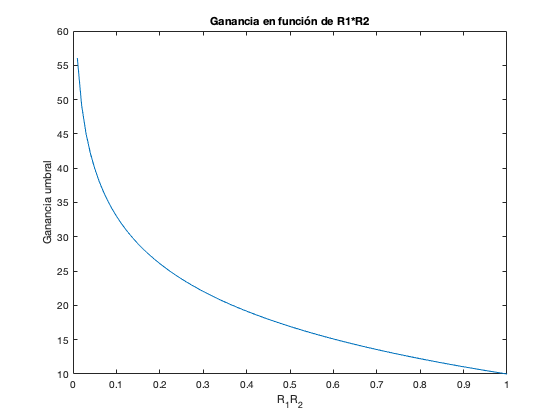

RR = 0:0.01:1; % R1*R2 de 0 a 1
Gth = alpha_c + log(1./(RR))/(2*L); % [1/cm] Ganancial umbral
plot(RR, Gth);
title("Ganancia en función de R1*R2");
ylabel("Ganancia umbral");
xlabel("R_1R_2");

## c) Si la eficiencia cuántica interna es de 0.65, ¿Cuánto vale la eficiencia cuántica diferencial para los dos casos anteriores?

La **eficiencia cuántica diferencial **aparece en la discusión sobre parámetros para medir las prestaciones de un láser y determina en cuanto se incrementa la potencia óptica de salida al incrementar la corriente de entrada.


$$\frac{d}{\mathrm{d}I}P_{\mathrm{cara}} =\frac{h\;w}{2\;e}\left(\frac{\eta_i \alpha_{\mathrm{es}} }{\left(\alpha_c +\alpha_{\mathrm{es}} \right)}\right)=\frac{h\;w}{2e}\eta_d$$


donde vemos que


$$\eta_d =\frac{\eta_i \alpha_{\mathrm{es}} }{\left(\alpha_c +\alpha_{\mathrm{es}} \right)}$$


El valor que necesitamos es $\alpha_{\mathrm{es}}$que representa las pérdidas por señal que escapa de la cavidad y viene dada por la expresión


$$\alpha_{\mathrm{es}} =\frac{1}{2L}\mathrm{ln}\left(\frac{1}{R_1 R_2 }\right)$$


effi = 0.65; % Eficiencia interna
alpha_esp = log(1/(R1*R2)) / (2*L); % Perdidas salida de señal de la cavidad
effd_a = effi*alpha_esp / (alpha_c + alpha_esp)

effd_a = 0.4520

alpha_esp = log(1/(R1*R2_b)) / (2*L); % Perdidas salida de señal de la cavidad
effd_b = effi*alpha_esp / (alpha_c + alpha_esp)

effd_b = 0.3607